
ctrlFreshMediaDataPath = 'C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\25_08_08_M231_PSD_PEDOT\PEDOT_Media_Fresh_Media.raw.h5';
cells72HrDataPath = 'C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\25_08_08_M231_PSD_PEDOT\PEDOT_Cells_72hr.raw.h5';


rawpath = '/recordings/rec0000/well000/groups/routed';
wellID = 1;


ctrlMediaRawData = mxw.fileManager(ctrlFreshMediaDataPath,wellID);

cellsRawData_72hr = mxw.fileManager(cells72HrDataPath,wellID);

samplingFrequency = 20000;
highPassCutOff = 0.1;
bandwidth = [200 3500];
numSeconds = 5;

ctrlMediaTable = createRecordingTable(ctrlMediaRawData,numSeconds,1,1)

ctrlMediaTable = 101×4 table
    electrodeNums      xs       ys         rawTraces   
    _____________    ______    _____    _______________

         897          297.5       70    1×100000 double
         912            560       70    1×100000 double
         932            910       70    1×100000 double
        1072           3360       70    1×100000 double
        1082           3535       70    1×100000 double
        1092           3710       70    1×100000 double
        1992            210    157.5    1×100000 double
        2007          472.5    157.5    1×100000 double
        2172           3360    157.5    1×100000 double
        3082             35      245    1×100000 double
        3087          122.5      245    1×100000 double
        3092            210      245    1×100000 double
        3112            560      245    1×100000 d

ctrlMediaTable = highPassFilterTraces(ctrlMediaTable,highPassCutOff,samplingFrequency)

ctrlMediaTable = 101×5 table
    electrodeNums      xs       ys         rawTraces       filteredTraces 
    _____________    ______    _____    _______________    _______________

         897          297.5       70    1×100000 double    1×100000 double
         912            560       70    1×100000 double    1×100000 double
         932            910       70    1×100000 double    1×100000 double
        1072           3360       70    1×100000 double    1×100000 double
        1082           3535       70    1×100000 double    1×100000 double
        1092           3710       70    1×100000 double    1×100000 double
        1992            210    157.5    1×100000 double    1×100000 double
        2007          472.5    157.5    1×100000 double    1×100000 double
        2172           3360    157.5    1×100000 d

[ctrlMediaTable, ctrlAvPSD, ctrlAvfreq] = calculatePSDs(ctrlMediaTable,samplingFrequency)

ctrlMediaTable = 101×7 table
    electrodeNums      xs       ys         rawTraces       filteredTraces          PSDs          frequencies  
    _____________    ______    _____    _______________    _______________    ______________    ______________

         897          297.5       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double
         912            560       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double
         932            910       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double
        1072           3360       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double
        1082           3535       70    1×100000 double    1×10000

ctrlAvPSD = 	1.0e+-10 *

    0.1881
    0.2138
    0.1032
    0.0590
    0.0379
    0.0244
    0.0167
    0.0116
    0.0095
    0.0080


ctrlAvfreq =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



[ctrlAvRMS] = calculateAverageRMS(ctrlAvPSD,ctrlAvfreq,bandwidth)

ctrlAvRMS = 1.4343e-06

disp(ctrlAvRMS);

   1.4343e-06




ctrlMediaTable = calculateRMSs(ctrlMediaTable, bandwidth)

ctrlMediaTable = 101×8 table
    electrodeNums      xs       ys         rawTraces       filteredTraces          PSDs          frequencies         RMSs   
    _____________    ______    _____    _______________    _______________    ______________    ______________    __________

         897          297.5       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double    1.4872e-06
         912            560       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double    1.3542e-06
         932            910       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double    1.5018e-06
        1072           3360       70    1×100000 double    1×100000 doubl

ctrlMediaTable = calculateResistances(ctrlMediaTable, bandwidth)

ctrlMediaTable = 101×9 table
    electrodeNums      xs       ys         rawTraces       filteredTraces          PSDs          frequencies         RMSs       resistances
    _____________    ______    _____    _______________    _______________    ______________    ______________    __________    ___________

         897          297.5       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double    1.4872e-06       39167   
         912            560       70    1×100000 double    1×100000 double    1×10001 double    1×10001 double    1.3542e-06       32475   
         932            910       70    1×100000 double    1×100000 double    1×10001 double    1×10001 

% limits = [10E3 200E3];
% clf;
% plotMap(ctrlMediaTable,limits);

nRecordings = 44;
controlTable = ctrlMediaTable;

cellsTableArray = cell(1,nRecordings);
cellsAvRMSArray = zeros(1,nRecordings);
cellsAvPSDArray = cell(1,nRecordings);
cellsAvDiffPSDArray = cell(1,nRecordings);
cellsAvFreqArray = cell(1,nRecordings);


for i = 1:1:nRecordings

    cellsTableArray{i} = createRecordingTable(cellsRawData_72hr,numSeconds,1,i);
    cellsTableArray{i} = highPassFilterTraces(cellsTableArray{i},highPassCutOff,samplingFrequency);

    [cellsTableArray{i},cellsAvPSDArray{i},cellsAvFreqArray{i}] = calculatePSDs(cellsTableArray{i},samplingFrequency);
    [cellsAvRMSArray(i)] = calculateAverageRMS(cellsAvPSDArray{i},cellsAvFreqArray{i},bandwidth);

    [cellsTableArray{i},cellsAvDiffPSDArray{i}] = calculateDifferentialPSDs(cellsTableArray{i},controlTable);

    cellsTableArray{i} = calculateDifferentialRMSs(cellsTableArray{i}, bandwidth);
    cellsTableArray{i} = calculateDifferentialResistances(cellsTableArray{i}, bandwidth);
    
    disp(cellsAvRMSArray(i))
end

   1.4928e-06

   1.4682e-06

   1.4610e-06

   1.4647e-06

   1.4698e-06

   1.4872e-06

   1.4796e-06

   1.5506e-06

   1.5172e-06

   1.4774e-06

   1.5058e-06

   1.5174e-06

   1.5025e-06

   1.5752e-06

   1.6591e-06

   1.7480e-06

   1.9294e-06

   2.1172e-06

   2.2944e-06

   2.4527e-06

   2.5893e-06

   2.7114e-06

   2.8079e-06

   2.8738e-06

   2.9299e-06

   2.9852e-06

   3.0147e-06

   3.0335e-06

   3.0162e-06

   3.0149e-06

   2.9970e-06

   2.9689e-06

   2.9241e-06

   2.8890e-06

   2.8508e-06

   2.8148e-06

   2.7796e-06

   2.7485e-06

   2.7010e-06

   2.6764e-06

   2.6531e-06

   2.6326e-06

   2.6072e-06

   2.5913e-06




cellsAvPSDArray = cell2mat(cellsAvPSDArray);
cellsAvDiffPSDArray = cell2mat(cellsAvDiffPSDArray);
cellsAvFreqArray = cell2mat(cellsAvFreqArray);


clf('reset');

loglog(ctrlAvfreq,sqrt(ctrlAvPSD));

hold on;
loglog(cellsAvFreqArray,sqrt(cellsAvPSDArray));
hold off;

colorMapLength = nRecordings + 1;
red = [1,0,0];
blue = [0,0,1];
black = [0,0,0];


colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
colours_ctrl = black;
ax=gca;
ax.ColorOrder = cat(1,colours_ctrl,colours_scale);


legend('MDA-MB-231 Cells at Hour 1' ...
    ,'', '','','','','','','','','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','','','','','MDA-MB-231 Cells at Hour 45','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','', ...
    'MDA-MB-231 Cells at Hour 70','Media Control')

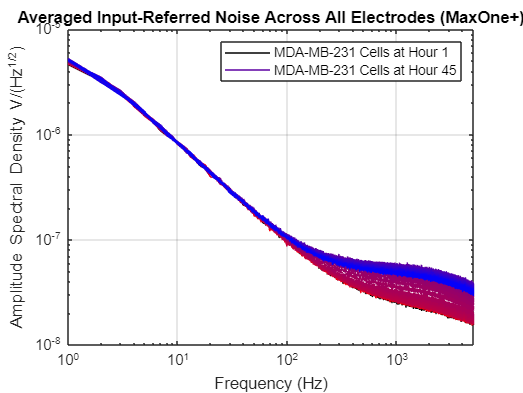


xlim([0 5000]);
xlabel('Frequency (Hz)');
ylabel('Amplitude Spectral Density V/(Hz^{1/2})')
title('Averaged Input-Referred Noise Across All Electrodes (MaxOne+)')
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')

clf('reset');



loglog(cellsAvFreqArray,cellsAvDiffPSDArray());


colorMapLength = nRecordings + 1;
red = [1,0,0];
blue = [0,0,1];
black = [0,0,0];


colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
colours_ctrl = black;
ax=gca;
ax.ColorOrder = cat(1,colours_ctrl,colours_scale);


legend('MDA-MB-231 Cells at Hour 1' ...
    ,'', '','','','','','','','','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','','','','','MDA-MB-231 Cells at Hour 45','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','', ...
    'MDA-MB-231 Cells at Hour 70','Media Control')

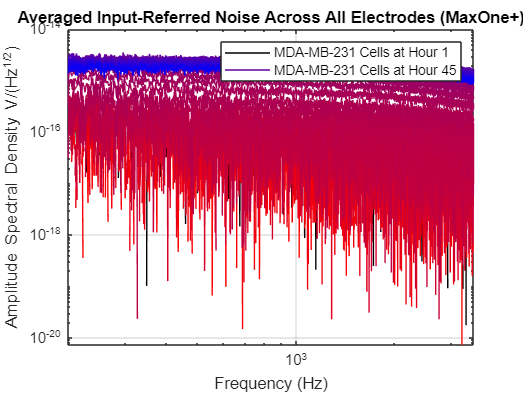


xlim([bandwidth(1) bandwidth(2)]);
xlabel('Frequency (Hz)');
ylabel('Amplitude Spectral Density V/(Hz^{1/2})')
title('Averaged Input-Referred Noise Across All Electrodes (MaxOne+)')
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')

function T = createRecordingTable(rawData,numSeconds,correctionFactor,recordingNum)
        
        startSample = 1;
        subset = [1 rawData.fileObj(1).nChannels];
        subset = [400 500];

        electrodeNums = rawData.rawMap(1).map.electrode(subset(1):subset(2));
        xs = rawData.rawMap(1).map.x(subset(1):subset(2));
        ys = rawData.rawMap(1).map.y(subset(1):subset(2));
        rawTraces = rawData.extractRawData(startSample,numSeconds*rawData.fileObj(1).samplingFreq,'file',recordingNum);
         
        rawTraces = transpose(rawTraces(:,subset(1):subset(2)));
        rawTraces = (rawTraces./(1E6))*correctionFactor;

        T = table(electrodeNums,xs,ys,rawTraces);
        T = sortrows(T);
end
    
function T = highPassFilterTraces(T, highPassCutOff,samplingFreq)
        
        [sos,g] = butter(1,highPassCutOff/(samplingFreq/2),"high");
        filteredTraces = filtfilt(sos,g,double(transpose(T.rawTraces)));
        T = addvars(T,transpose(filteredTraces),'NewVariableNames','filteredTraces');
        
end

function [T, avPSD, avFreq] = calculatePSDs(T,samplingFreq)
    
        resolution = 1;
        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        [PSDs,frequencies] = pwelch(transpose(T.filteredTraces),window,overlap,nfft,samplingFreq);
        
        avPSD = sum(PSDs,2)/size(PSDs,2);
        avFreq = frequencies;

        frequencies = repmat(frequencies,1,size(PSDs,2));
        PSDs = transpose(PSDs);
        frequencies = transpose(frequencies);

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  
        
end

function [T,avDiffPSD] = calculateDifferentialPSDs (T,controlT)

        differentialPSDs = transpose(T.PSDs) - transpose(controlT.PSDs);

        avDiffPSD = sum(differentialPSDs,2)/size(differentialPSDs,2);

        real(max(differentialPSDs,0));

        T = addvars(T, transpose(differentialPSDs), 'NewVariableNames','diffPSDs');
    
end

function avRMS = calculateAverageRMS(avPSD,avFreq,bandwidth)

        f = avFreq(bandwidth(1):bandwidth(2));
        PSD = avPSD(bandwidth(1):bandwidth(2));

        avRMS = sqrt(trapz(f,PSD));

end

function T = calculateRMSs(T,bandwidth)

        len = height(T);
        RMSs = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            PSD = transpose(T.PSDs(i,bandwidth(1):bandwidth(2)));
            RMSs(i) = sqrt(trapz(f,PSD)); 
        end

        T = addvars(T, RMSs, 'NewVariableNames','RMSs');

end

function T = calculateDifferentialRMSs(T,bandwidth)

        len = height(T);
        diffRMSs = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            diffPSD = transpose(T.diffPSDs(i,bandwidth(1):bandwidth(2)));
            diffRMSs(i) = sqrt(trapz(f,diffPSD)); 
        end

        T = addvars(T, diffRMSs, 'NewVariableNames','diffRMSs');

end

function T = calculateResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        resistances = (transpose(T.RMSs).^2)./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(resistances), 'NewVariableNames','resistances');

end


function T = calculateDifferentialResistances (T,bandwidth)
         
        boltzman = 1.38E-23;
        temp = 310;

        diffResistances = (transpose(T.diffRMSs).^2)./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(diffResistances), 'NewVariableNames','diffResistances');

end



function plotMap(T,limits)

        x  = T.xs;
        y  = T.ys;
        v  = T.resistances;
        id = T.electrodeNums;
        
        pixelSize = 11.5;
        half = pixelSize / 2;
        
        
        colorMapLength = 256;
        blue = [0,0,1];
        white = [1,1,1];
        cmap = [linspace(white(1),blue(1),colorMapLength)', linspace(white(2),blue(2),colorMapLength)', linspace(white(3),blue(3),colorMapLength)'];
        
                  
        vmin = limits(1);
        vmax = limits(2);
        
        figure;
        hold on
        
        for i = 1:numel(v)
        
            idx = round( (v(i)-vmin) / (vmax-vmin) * (size(cmap,1)-1) ) + 1;
            idx = max(1, min(idx, size(cmap,1)));  
        
            Xc = [x(i)-half, x(i)+half, x(i)+half, x(i)-half];
            Yc = [y(i)-half, y(i)-half, y(i)+half, y(i)+half];
        
            patch(Xc, Yc, 'w', ...        
                'FaceColor', 'none', ...
                'EdgeColor', cmap(idx,:), ...
                'LineWidth', 0.8);
        end
        
        axis equal;
        set(gca, 'YDir', 'reverse');  
        set(gca, 'XDir', 'normal'); 
        colormap(cmap);
        caxis([vmin vmax]);           
        colorbar;
        title('Electrode map');
        ylim([0 2100]);
        xlim([0 3850]);
        
        dcm = datacursormode(gcf);
        set(dcm,'Enable','on','UpdateFcn',@idTip);
        
            function txt = idTip(~, evt)
                pos = evt.Position;   
                [~, idx] = min( hypot(x - pos(1), y - pos(2)) );
                txt = {
                    ['ID: ' num2str(id(idx))]
                    ['Value: ' num2str(v(idx))]
                    ['X (\mum): ' num2str(x(idx))]
                    ['Y (\mum): ' num2str(y(idx))]
                };
            end

end
